# Programming Assignment: Gradient Based Planner

## **INTRODUCTION**

In this assignment you will be developing code to guide a robot from one location to another in a 2 dimensional configuration space using artificial potential fields. The figure below depicts a plot of the energy surface associated with our sample environment and the state of the robot is modeled by the red sphere which we can be thought of as rolling down the energy surface towards the goal location.

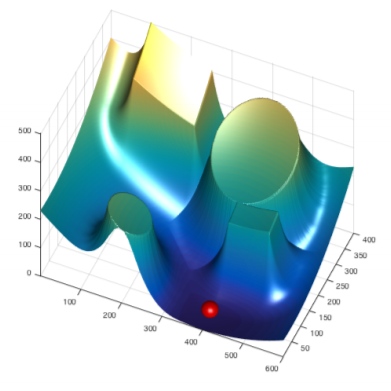

## **IMPLEMENTATION**

Your job is to complete the function named `GradientBasedPlanner` which is used to control the motion of the robot. The signature of the function is given below

The input arguments to this function are explained below. 

-   ` f` : A 2D array containing the potential function values. 

-    `start_coords` : An array specifying the coordinates of the start location the first entry is the x coordinate and the second the y

-    `end_coords` : An array specifying the coordinates of the goal the first entry is the x coordinate and the second the y 

-    `max_its` : The maximum number of iterations that should be tried by the planner

## **ALGORITHM**

The section of code that you are asked to complete should perform the following procedure: 

- On every iteration the planner should update the position of the robot based on the gradient values contained in the arrays `gx` and `gy`. Make sure you normalize the gradient vectors. 

- Update the route by adding the new position of the robot to the end of the route array. Note that the distance between successive locations in the route should not be greater than 1.0. 

- Continue the same procedure until the distance between the robot’s current position and the goal is less than 2.0 or the number of iterations exceeds the value contained in `max_its`.

## **NOTE** : 

- For reducing computation time, the displays have been turned off. If you wish to observe the images change the "`display_" `values accordingly. Please observe one image at a time since the code times out otherwise.

- If you wish to observe the animation of the route followed by the ball, please download the skeleton code from the summary window in the previous screen and plug in your code in `GradientBasedPlanner.m` 

% Generate some points
nrows = 400;
ncols = 600;
obstacle = false(nrows, ncols);
[x, y] = meshgrid (1:ncols, 1:nrows);

% Generate some obstacle
obstacle (300:end, 100:250) = true;
obstacle (150:200, 400:500) = true;
t = ((x - 200).^2 + (y - 50).^2) < 50^2;
obstacle(t) = true;
t = ((x - 400).^2 + (y - 300).^2) < 100^2;
obstacle(t) = true;

% Compute distance transform
d = bwdist(obstacle);

% Rescale and transform distances
d2 = (d/100) + 1;
d0 = 2;
nu = 800;

repulsive = nu*((1./d2 - 1/d0).^2);
repulsive (d2 > d0) = 0;

goal = [400, 50];

xi = 1/700;
attractive = xi * ( (x - goal(1)).^2 + (y - goal(2)).^2 );
f = attractive + repulsive;

start = [50, 350];
route = GradientBasedPlanner (f, start, goal, 1000);

display_repulsive = true; % Display Repulsive Potential
display_attractive = true; % Display Attractive Potential
display_cspace = true; % Display Configuration Space
display_totalpot = true; % Display complete potential 
display_quiverplot = true; % Display Quiverplot

if isequal(display_repulsive, true) 
    figure;
    m = mesh (repulsive);
    m.FaceLighting = 'phong';
    axis equal;
end

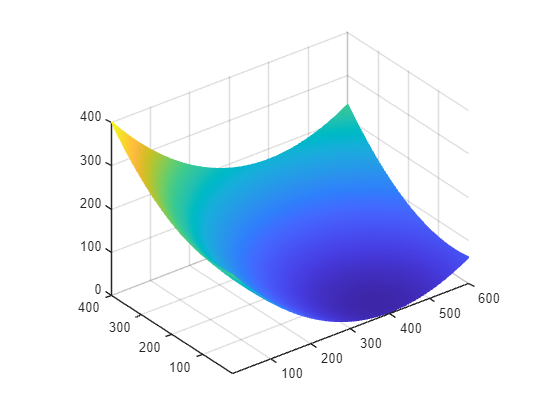


if isequal(display_attractive, true) 
    figure;
    m = mesh (attractive);
    m.FaceLighting = 'phong';
    axis equal;
end

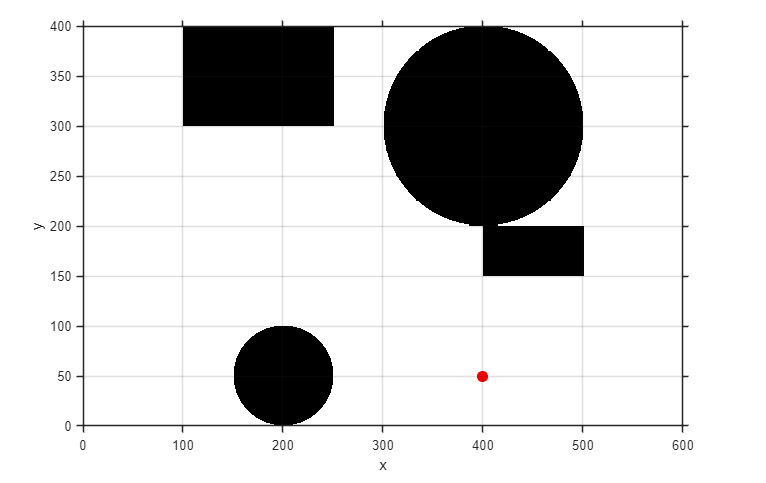


if isequal(display_cspace, true) 
    figure;
    imshow(~obstacle);
    hold on;
    plot (goal(1), goal(2), 'r.', 'MarkerSize', 25);
    hold off;
    axis ([0 ncols 0 nrows]);
    axis xy;
    axis on;
    xlabel ('x');
    ylabel ('y');
    grid on;
end

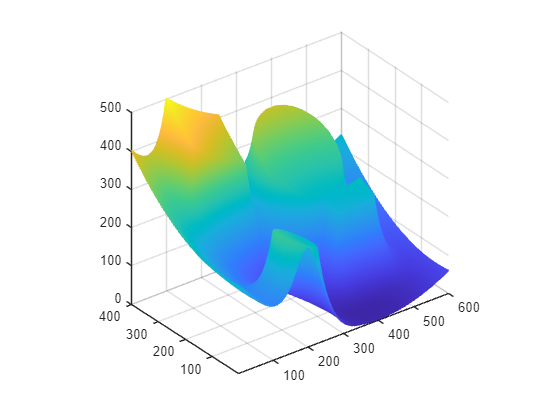


if isequal(display_totalpot, true) 
    figure;
    m = mesh (f);
    m.FaceLighting = 'phong';
    axis equal;
end

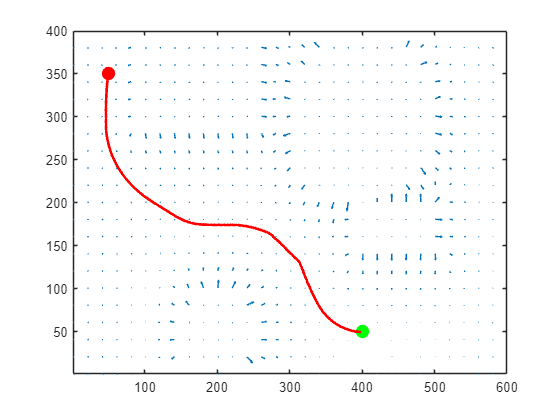


if isequal(display_quiverplot, true)
    [gx, gy] = gradient (-f);
    skip = 20;
    figure;
    xidx = 1:skip:ncols;
    yidx = 1:skip:nrows;
    quiver (x(yidx,xidx), y(yidx,xidx), gx(yidx,xidx), gy(yidx,xidx), 0.4);
    axis ([1 ncols 1 nrows]);
    hold on;    
    ps = plot(start(1), start(2), 'r.', 'MarkerSize', 30);
    pg = plot(goal(1), goal(2), 'g.', 'MarkerSize', 30);
    p3 = plot (route(:,1), route(:,2), 'r', 'LineWidth', 2);
end

function route = GradientBasedPlanner(f, start_coords, end_coords, max_its)
    % GradientBasedPlanner : This function plans a path through a 2D
    % environment from a start to a destination based on the gradient of the
    % function f which is passed in as a 2D array. The two arguments
    % start_coords and end_coords denote the coordinates of the start and end
    % positions respectively in the array while max_its indicates an upper
    % bound on the number of iterations that the system can use before giving
    % up.
    % The output, route, is an array with 2 columns and n rows where the rows
    % correspond to the coordinates of the robot as it moves along the route.
    % The first column corresponds to the x coordinate and the second to the y coordinate
    %
    % NOTE: Once the route array has been updated, pass the array as is instead of appending with zeros or NAN
    
    [gx, gy] = gradient(-f);
    
    %%% All of your code should be between the two lines of stars.
    % *******************************************************************
    route = start_coords;
    count = 1;
    nrm = norm(squeeze(route(count,:))-end_coords);

    while((nrm > 2) && ((count-1) < max_its))
        % this is a better way, but the grader doesn't think so.    
        %     x = route(count,1);
        %     y = route(count,2);
        %     gradx = interp2(gx,x,y);
        %     grady = interp2(gy,x,y);
        grad_idx = min(max(round(route(count, :)), 1), max(size(gx)));
        gradx = gx(grad_idx(2), grad_idx(1));
        grady = gy(grad_idx(2), grad_idx(1));
        v = [gradx grady];
        u = v / norm(v);
        count = count + 1;
        route(count, :) = route(count-1, :) + u;
        nrm = norm(squeeze(route(count, :)) - end_coords);
    end
    % *******************************************************************
end